Ejemplo de aplicación de la FFT

A1=1; f1=0.25;
A2=0; f2=0.125;
A3=0; f3=0.0625;
A4=0; f4=0.03125;
A5=0; f5=0.015625;

Se cosntruye la señal de tiempo discreto a partir de los parámetros establecidos. Copare con la gráfica obtenida en excel

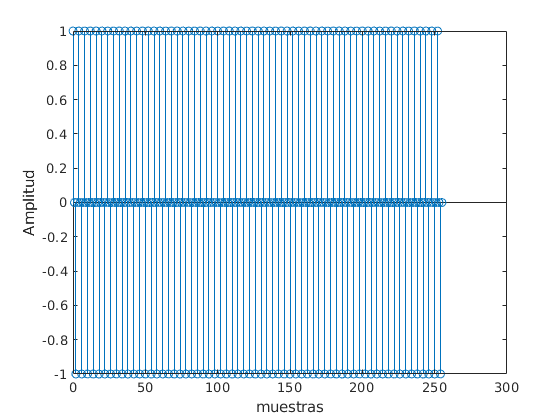

N=255;
n=0:N;
xn=A1*cos(2*pi*f1*n)+A2*cos(2*pi*f2*n)+A3*cos(2*pi*f3*n)+A4*cos(2*pi*f4*n)+A5*cos(2*pi*f5*n);
figure
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')

Aplicación de la FFT

xk=fft(xn);

Graficas de parte real e imaginaria, compare con lo obtenido en excel.

¿Por qué son diferentes en amplitud?

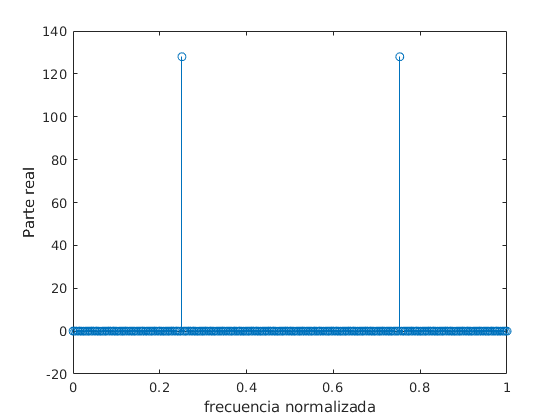

figure
f=n/N;
stem(f,real(xk))
xlabel('frecuencia normalizada')
ylabel('Parte real')

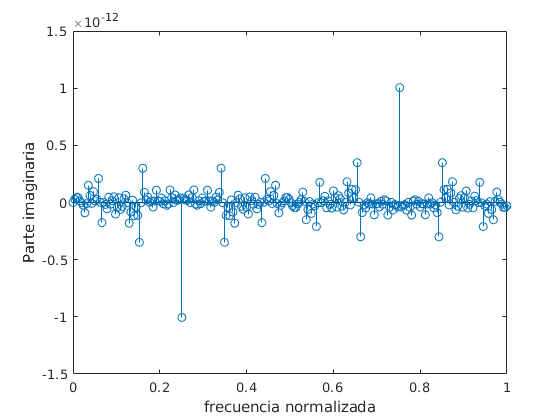

figure
stem(f,imag(xk))
xlabel('frecuencia normalizada')
ylabel('Parte imaginaria')

Gráficas de magnitud y fase, compare con lo obtenido en excel.

¿Qué diferencias encuentra?

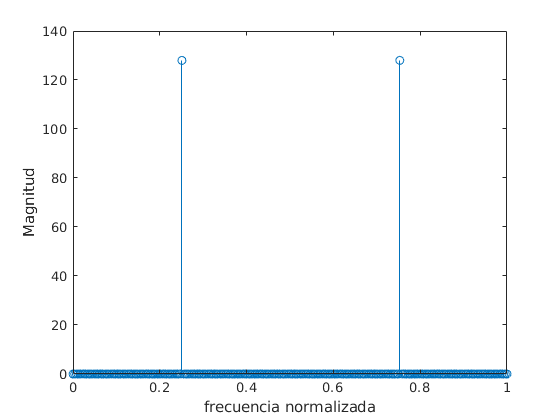

stem(f,abs(xk))
xlabel('frecuencia normalizada')
ylabel('Magnitud')

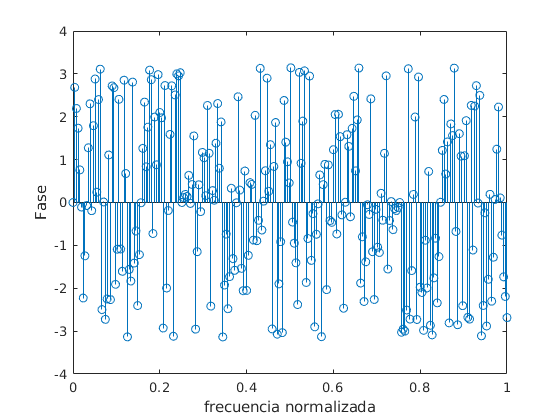

figure
stem(f,angle(xk))
xlabel('frecuencia normalizada')
ylabel('Fase')